% This program plots out the absorption coefficients for all the experiment test cases.
clc; clear all; close all;
load('Strut Lattice.mat');

color = [0 0.8 0;0.8 0 0;0 0 0.8;0.8 0.6 0];
line_style = ["--" ":" "-" "-."];
marker = ['o','+','x','s'];

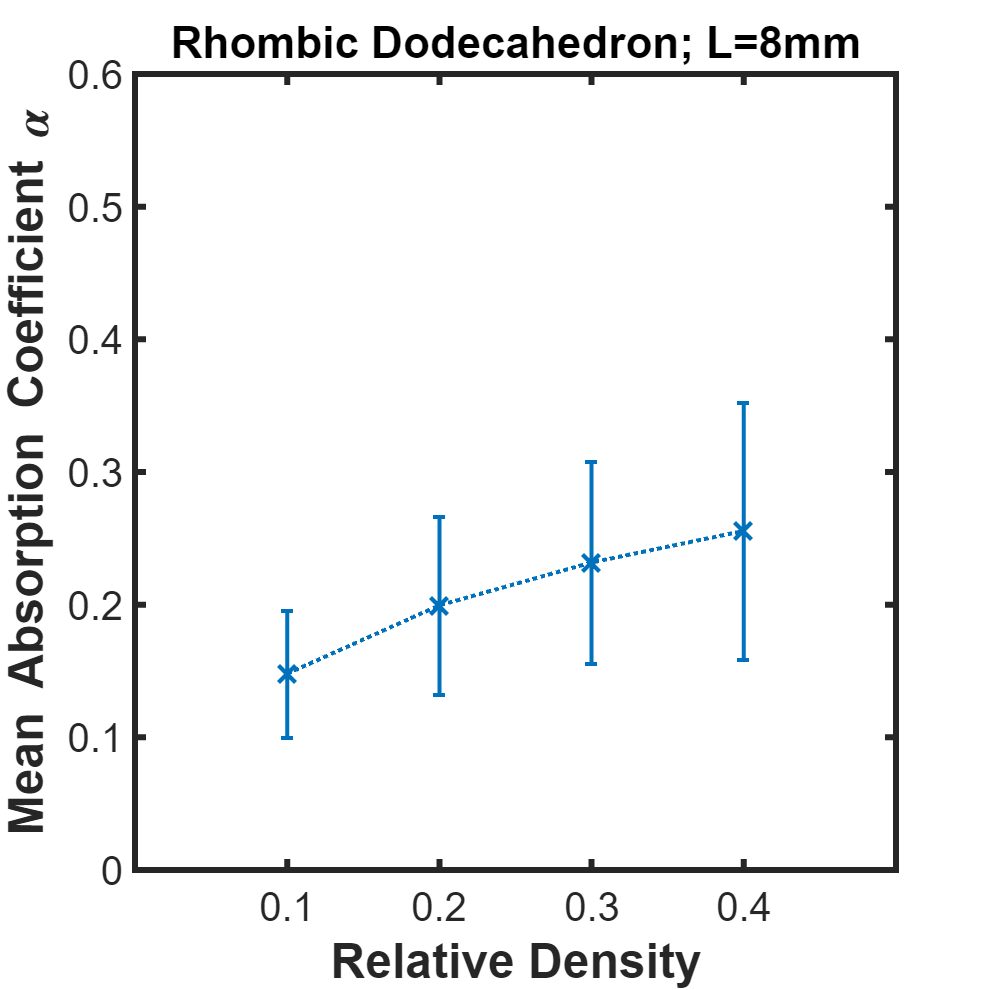

% Same Unit Cell and Cell Size.
figure('Position', [100 100 660 660]);
for idx_cell = 1:length(unit_cell)
	for idx_length = 1:length(cell_length)
        UC = unit_cell(idx_cell);
        L = cell_length(idx_length);
        cases = find(case_idx(:,2)==idx_cell & case_idx(:,3)==idx_length);
        for idx_case = 1:length(cases)
            RD = rel_density(case_idx(cases(idx_case),4));
			
            f = freq(:,cases(idx_case));
			alpha_expt = SAC_expt(:,cases(idx_case));
			label = sprintf("RD %.0f%%",RD*100);
			
			plot(f,alpha_expt,'DisplayName',label,'LineWidth',3);
			hold on;
		end
		ax = gca;
	    ax.FontSize = 20;
        ax.Title.String = sprintf("%s; L=%.0fmm",UC,L);
	    ax.XLim = [1000 6300];
	    ax.YLim = [0 1];
	    ax.XTick = 1000:1000:6300;
	    ax.YTick = 0:0.2:1.0;
	    ax.XLabel.String = "Frequency (Hz)";
	    ax.YLabel.String = "Absorption Coefficient \alpha";
	    ax.XLabel.FontSize = 24;
        ax.YLabel.FontSize = 24;
        ax.XLabel.FontWeight = 'bold';
        ax.YLabel.FontWeight = 'bold';
        ax.Box = 'on';
        ax.LineWidth = 3;
	    legend('Location','northeast','NumColumns',1);
	    legend('FontSize',24);
	    legend('boxoff');
		
		% Saves graph as .tif file. Open them up to see.
		print(sprintf("Expt-%s-L=%.0fmm.tif",UC,L),'-dtiff','-r500');
		hold off;
		
		count = 0; w = []; alpha_expt_mean = []; alpha_expt_std = [];
		for idx_case = 1:length(cases)
            RD = rel_density(case_idx(cases(idx_case),4));
			
            f = freq(:,cases(idx_case));
			alpha_expt = SAC_expt(:,cases(idx_case));
			label = sprintf("RD %.0f%%",RD*100);
			
			count = count + 1;
			w(count) = RD;
			alpha_expt_mean(count) = mean(alpha_expt);
			alpha_expt_std(count) = std(alpha_expt);
        end
		errorbar(w,alpha_expt_mean,alpha_expt_std,'lineStyle',':','Marker','x', ...
			'MarkerSize',12,'LineWidth',2','HandleVisibility','off');
		
		ax = gca;
		ax.FontSize = 20;
		ax.Title.String = sprintf("%s; L=%.0fmm",UC,L);
		ax.XLim = [0 0.5];
		ax.YLim = [0 0.6];
		ax.XTick = 0.1:0.1:0.4;
		ax.YTick = 0:0.1:0.6;
		ax.XLabel.String = "Relative Density";
		ax.YLabel.String = "Mean Absorption Coefficient \alpha";
		ax.XLabel.FontSize = 24;
        ax.YLabel.FontSize = 24;
        ax.XLabel.FontWeight = 'bold';
        ax.YLabel.FontWeight = 'bold';
        ax.Box = 'on';
        ax.LineWidth = 3;
		legend('off');
		
		% Saves graph as .tif file. Open them up to see.
		print(sprintf("MeanStd-%s-L=%.0fmm.tif",UC,L),'-dtiff','-r500');
		hold off;
	end
end

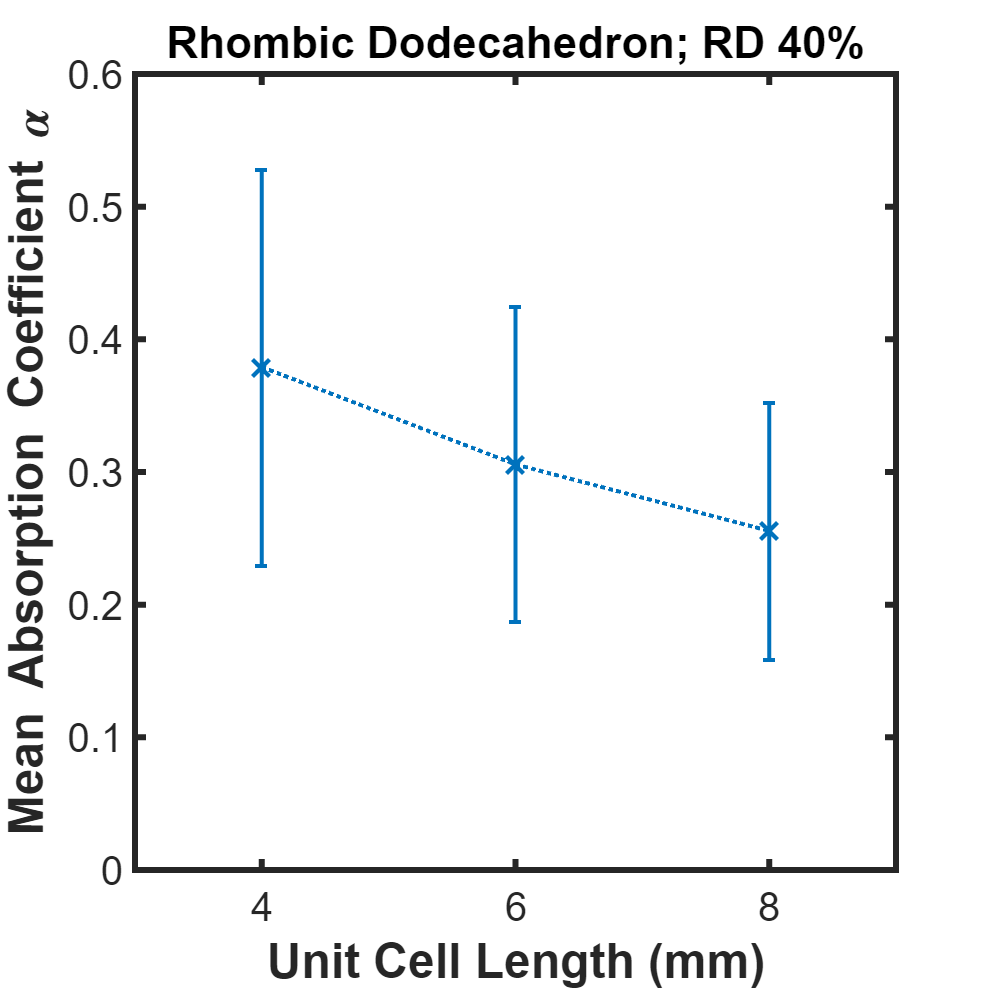

% Same Unit Cell and Relative Density.
figure('Position', [100 100 660 660]);
for idx_cell = 1:length(unit_cell)
	for idx_RD = 1:length(rel_density)
        UC = unit_cell(idx_cell);
        RD = rel_density(idx_RD);
        cases = find(case_idx(:,2)==idx_cell & case_idx(:,4)==idx_RD);
        for idx_case = 1:length(cases)
            L = cell_length(case_idx(cases(idx_case),3));
			
            f = freq(:,cases(idx_case));
			alpha_expt = SAC_expt(:,cases(idx_case));
			label = sprintf("L=%.0fmm",L);
			
			plot(f,alpha_expt,'DisplayName',label,'LineWidth',3);
			hold on;
		end
		ax = gca;
	    ax.FontSize = 20;
        ax.Title.String = sprintf("%s; RD %.0f%%",UC,RD*100);
	    ax.XLim = [1000 6300];
	    ax.YLim = [0 1];
	    ax.XTick = 1000:1000:6300;
	    ax.YTick = 0:0.2:1.0;
	    ax.XLabel.String = "Frequency (Hz)";
	    ax.YLabel.String = "Absorption Coefficient \alpha";
	    ax.XLabel.FontSize = 24;
        ax.YLabel.FontSize = 24;
        ax.XLabel.FontWeight = 'bold';
        ax.YLabel.FontWeight = 'bold';
        ax.Box = 'on';
        ax.LineWidth = 3;
	    legend('Location','northeast','NumColumns',1);
	    legend('FontSize',24);
	    legend('boxoff');
		
		% Saves graph as .tif file. Open them up to see.
		print(sprintf("Expt-%s-RD %.0f%%.tif",UC,RD*100),'-dtiff','-r500');
		hold off;
		
		count = 0; w = []; alpha_expt_mean = []; alpha_expt_std = [];
		for idx_case = 1:length(cases)
            L = cell_length(case_idx(cases(idx_case),3));
			
            f = freq(:,cases(idx_case));
			alpha_expt = SAC_expt(:,cases(idx_case));
			label = sprintf("L=%.0fmm",L);
			
			count = count + 1;
			w(count) = L;
			alpha_expt_mean(count) = mean(alpha_expt);
			alpha_expt_std(count) = std(alpha_expt);
        end
		errorbar(w,alpha_expt_mean,alpha_expt_std,'lineStyle',':','Marker','x', ...
			'MarkerSize',12,'LineWidth',2','HandleVisibility','off');
		
		ax = gca;
		ax.FontSize = 20;
		ax.Title.String = sprintf("%s; RD %.0f%%",UC,RD*100);
		ax.XLim = [3 9];
		ax.YLim = [0 0.6];
		ax.XTick = [4 6 8];
		ax.YTick = 0:0.1:0.6;
		ax.XLabel.String = "Unit Cell Length (mm)";
		ax.YLabel.String = "Mean Absorption Coefficient \alpha";
		ax.XLabel.FontSize = 24;
        ax.YLabel.FontSize = 24;
        ax.XLabel.FontWeight = 'bold';
        ax.YLabel.FontWeight = 'bold';
        ax.Box = 'on';
        ax.LineWidth = 3;
		legend('off');
		
		% Saves graph as .tif file. Open them up to see.
		print(sprintf("MeanStd-%s-RD %.0f%%.tif",UC,RD*100),'-dtiff','-r500');
		hold off;
	end
end

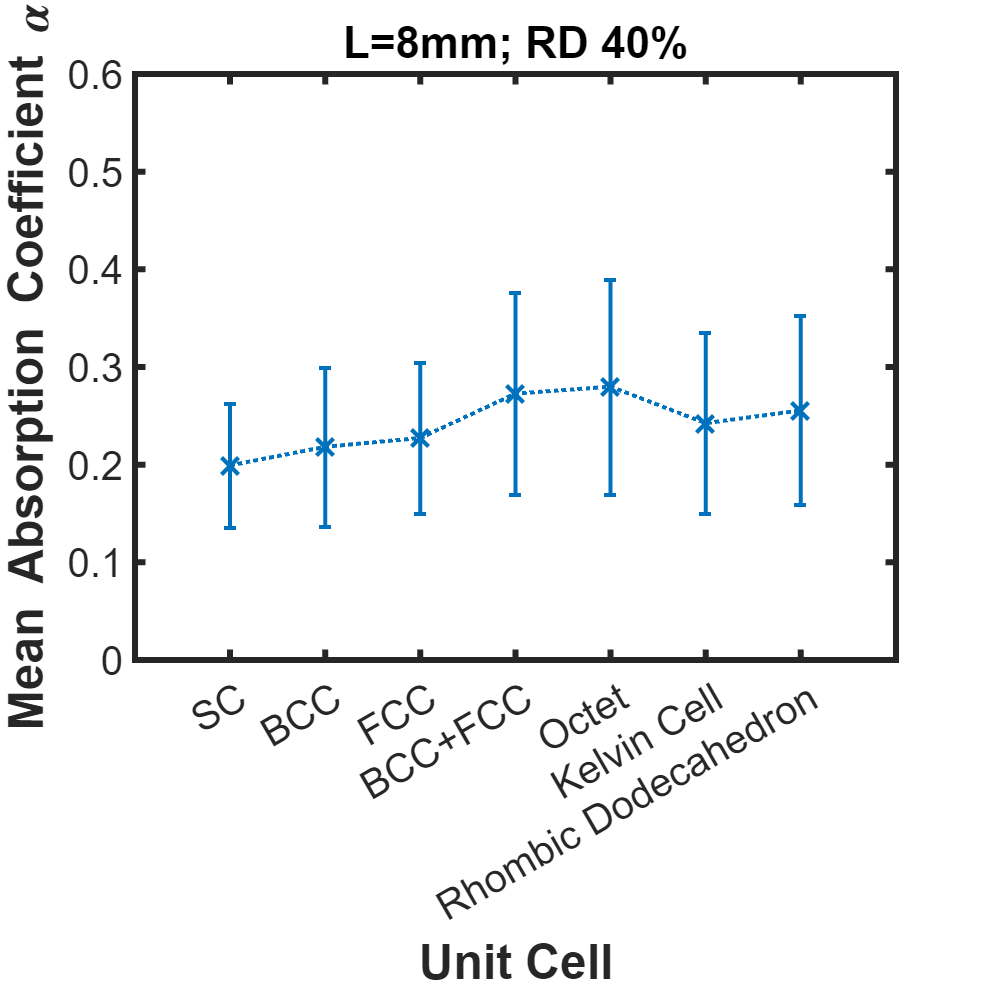

% Same Cell Length and Relative Density.
figure('Position', [100 100 660 660]);
for idx_density = 1:length(rel_density)
	for idx_length = 1:length(cell_length)
		cases = find(case_idx(:,3)==idx_length & case_idx(:,4)==idx_density);
		L = cell_length(idx_length);
		RD = rel_density(idx_density);
		
		for idx_cell = 1:length(unit_cell)
			f = freq(:,cases(idx_cell));
			alpha_expt = SAC_expt(:,cases(idx_cell));
			label = unit_cell(idx_cell);
			
			plot(f,alpha_expt,'DisplayName',label,'LineWidth',3);
			hold on;
		end
		ax = gca;
		ax.FontSize = 20;
		ax.Title.String = sprintf("L=%.0fmm; RD %.0f%%",L,RD*100);
		ax.XLim = [1000 6300];
		ax.YLim = [0 1];
		ax.XTick = 1000:1000:6300;
		ax.YTick = 0:0.2:1.0;
		ax.XLabel.String = "Frequency (Hz)";
		ax.YLabel.String = "Absorption Coefficient \alpha";
		ax.XLabel.FontSize = 24;
        ax.YLabel.FontSize = 24;
        ax.XLabel.FontWeight = 'bold';
        ax.YLabel.FontWeight = 'bold';
        ax.Box = 'on';
        ax.LineWidth = 3;
		legend('Location','northeast','NumColumns',1);
		legend('FontSize',20);
		legend('boxoff');
		
		% Saves graph as .tif file. Open them up to see.
		print(sprintf("Expt-L=%.0fmm-RD %.0f%%.tif",L,RD*100),'-dtiff','-r500');
		hold off;

        count = 0; w = []; alpha_expt_mean = []; alpha_expt_std = [];
		for idx_cell = 1:length(unit_cell)
            f = freq(:,cases(idx_cell));
			alpha_expt = SAC_expt(:,cases(idx_cell));
			label = unit_cell(idx_cell);
			
			count = count + 1;
			w(count) = count;
			alpha_expt_mean(count) = mean(alpha_expt);
			alpha_expt_std(count) = std(alpha_expt);
        end
		errorbar(w,alpha_expt_mean,alpha_expt_std,'lineStyle',':','Marker','x', ...
			'MarkerSize',12,'LineWidth',2','HandleVisibility','off');
		
		ax = gca;
		ax.FontSize = 20;
		ax.Title.String = sprintf("L=%.0fmm; RD %.0f%%",L,RD*100);
		ax.XLim = [0 8];
		ax.YLim = [0 0.6];
		ax.XTick = 1:1:7;
		ax.YTick = 0:0.1:0.6;
        ax.XTickLabel = unit_cell;
		ax.XLabel.String = "Unit Cell";
		ax.YLabel.String = "Mean Absorption Coefficient \alpha";
		ax.XLabel.FontSize = 24;
        ax.YLabel.FontSize = 24;
        ax.XLabel.FontWeight = 'bold';
        ax.YLabel.FontWeight = 'bold';
        ax.Box = 'on';
        ax.LineWidth = 3;
		legend('off');
		
		% Saves graph as .tif file. Open them up to see.
		print(sprintf("MeanStd-L=%.0fmm-RD %.0f%%.tif",L,RD*100),'-dtiff','-r500');
        hold off;
	end
end